x=[1.01, 2.2, 2.9, 4.03, 5.32 ,6.22, 8.56, 9.09];
y=[18.5, 76.2, 150.5, 365, 780, 1265, 3250, 7099];
xt=transpose(x);
van=[];
parfor i=1:length(xt)
    a=xt(i);
    van=[van;[a^3 a^2 a 1]];
end

Starting parallel pool (parpool) using the 'local' profile ...


connected to 2 workers.


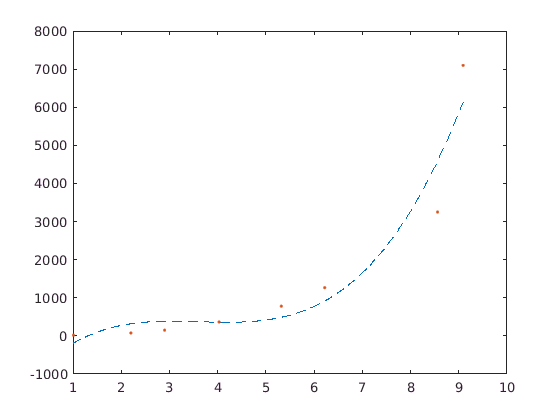

coeff=(transpose(van)*van)\transpose(van)*transpose(y);
points=[];
for i=1:.01:max(x)
    points=[points coeff_point(i,coeff)];
end
plot(1:.01:max(x),points,'--');hold on;scatter(x,y,'.');hold off;

function y = coeff_point(x,coeff)
    y=coeff(1)*x^3+coeff(2)*x^2+coeff(3)*x+coeff(4);
end